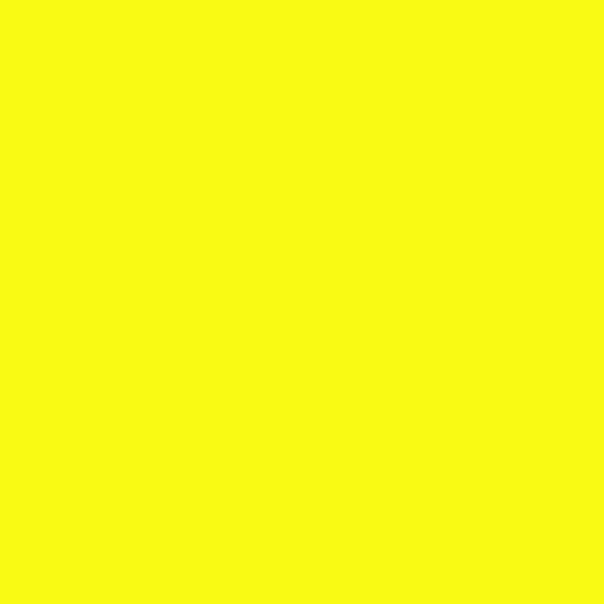

clear all
Xdim = 1;
Ydim = 1;
XNdim = 100;
YNdim = 100;
Tdim = 100;
c = 1;
G = 1;

Xl = linspace(-XNdim*Xdim,XNdim*Xdim,2*XNdim+1);
Yl = linspace(-YNdim*Ydim,YNdim*Ydim,2*YNdim+1);

[X,Y] = meshgrid(Xl,Yl);

XNdim = numel(Xl);
YNdim = numel(Yl);

rho  =((X).^2+(Y/2).^2<20.^2)*100.+.01*rand(size(X))+1;
% rho = imgaussfilt3(rho,1.);
pc = ((X).^2+(Y/2).^2<20.^2);
W = cat(3,rho+.01,-Y.*pc,X.*pc,0.*X);

DC = mat2gray(max(max(abs(X),abs(Y))-100+10,0));
DC = 3*DC.^2-2*DC.^3;
DC = 1-DC;

I = imshow(mat2gray(W(:,:,1)),[0 1],InitialMagnification=300);
hold on
colormap parula
axis equal
drawnow;

dt = .01;

F = cat(3,0.*X,-Y/100,-X/100,0.*X);
% [t,R] = ode45(@(t,Ys)ODE(t,Ys,DC,F,size(W)),[0 5],W(:));

% Rl = R(end,:);
% W = reshape(Rl,size(W));

for i=1:1000
p = W(:,:,1);
eps = 1;
alpha = .4;
fx = cat(3,W(:,:,2), W(:,:,2).^2./(W(:,:,1)+eps)+p+alpha*W(:,:,2),W(:,:,3).*W(:,:,2)./(W(:,:,1)+eps), W(:,:,2).*(W(:,:,4)+p)./(W(:,:,1)+eps));
fy = cat(3,W(:,:,3), W(:,:,3).*W(:,:,2)./(W(:,:,1)+eps),W(:,:,3).^2./(W(:,:,1)+eps)+p+alpha*W(:,:,3), W(:,:,3).*(W(:,:,4)+p)./(W(:,:,1)+eps));

if broken(W(:))
    a = 1;
end
% [dxfx,~] = gradient(fx);
% [~,dyfy] = gradient(fy);
% dxfx = .5*(fx-circshift(fx,1,1));
% dyfy = .5*(fy-circshift(fy,1,2));
dxfx = Dd(Dy(fx));
dyfy = Dd(Dx(fy));
W = W-dt*(dxfx+dyfy);%-F;

set(I,'CData',mat2gray(W(:,:,1)));
drawnow;
end



function R = ODE(t,R,D,F,s)
W = reshape(R,s);
p = W(:,:,1);
eps = 1;
alpha = .4;
fx = cat(3,W(:,:,2), W(:,:,2).^2./(W(:,:,1)+eps)+p+alpha*W(:,:,2),W(:,:,3).*W(:,:,2)./(W(:,:,1)+eps), W(:,:,2).*(W(:,:,4)+p)./(W(:,:,1)+eps));
fy = cat(3,W(:,:,3), W(:,:,3).*W(:,:,2)./(W(:,:,1)+eps),W(:,:,3).^2./(W(:,:,1)+eps)+p+alpha*W(:,:,3), W(:,:,3).*(W(:,:,4)+p)./(W(:,:,1)+eps));

if broken(W(:))
    a = 1;
end
% [dxfx,~] = gradient(fx);
% [~,dyfy] = gradient(fy);
% dxfx = .5*(fx-circshift(fx,1,1));
% dyfy = .5*(fy-circshift(fy,1,2));
dxfx = Du(Dx(fx));
dyfy = Du(Dy(fy));
W = -dxfx-dyfy;%-F;
% W = W.*D;
R = W(:);
end

function c=broken(W)
MiB = W<-1000;
MaB = W>1000;
MnB = isnan(W);
c = any(MiB(:)|MaB(:)|MnB(:));
end

function Sf=Dx(Si)
Sf = .50*((Si+circshift(Si,1,2))-(circshift(Si,1,1)+circshift(circshift(Si,1,2),1,1)));
end
function Sf=Dy(Si)
Sf = .50*((Si+circshift(Si,1,1))-(circshift(Si,1,2)+circshift(circshift(Si,1,1),1,2)));
end
function Sf=Du(Si)
Sf = .25*(Si+circshift(Si,-1,1)+circshift(Si,-1,2)+circshift(circshift(Si,-1,2),-1,1));
end
function Sf=Dd(Si)
Sf = .25*(Si+circshift(Si, 1,1)+circshift(Si, 1,2)+circshift(circshift(Si, 1,2), 1,1));
end